# 02686 - Scientific Computing for Differential Equations

## 01 - Test Equation for ODEs

x0 = 1;
t0 = 0;
tN = 10;
N = 100;

[T,X] = ExplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T1,X1] = ImplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T2,X2] = ClassicalRungeKuttaFixedStepSize(@testEquationJac,t0,tN,N,x0);



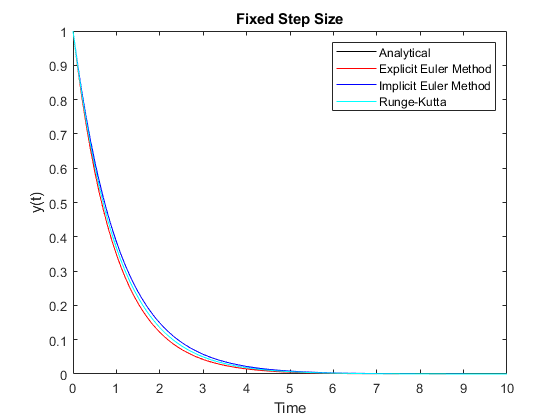

plot(T,exact(T),"black");
hold on;
plot(T,X,"red");
hold on;
plot(T1,X1,"blue");
hold on;
plot(T2,X2,"cyan");
hold off;
title("Fixed Step Size");
legend("Analytical","Explicit Euler Method","Implicit Euler Method","Runge-Kutta");
xlabel("Time");
ylabel("y(t)");

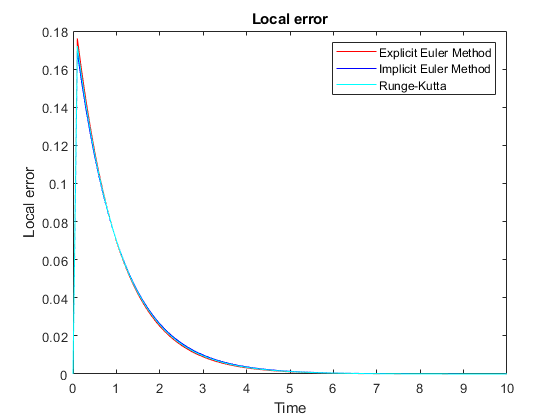

% Local and global truncation errors

l = local_error(T,X);
l1 = local_error(T1,X1);
l2 = local_error(T2,X2);

plot(T,l,"red");
hold on;
plot(T1,l1,"blue");
hold on;
plot(T2,l2,"cyan");
hold off;
title("Local error");
legend("Explicit Euler Method","Implicit Euler Method","Runge-Kutta");
xlabel("Time");
ylabel("Local error");

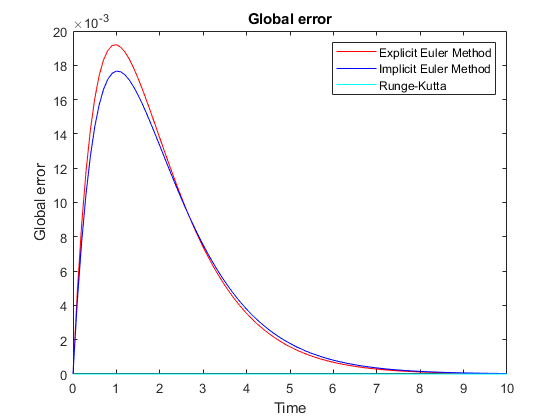

% Local and global truncation errors
g = global_error(T,X);
g1 = global_error(T1,X1);
g2 = global_error(T2,X2);

plot(T,g,"red");
hold on;
plot(T1,abs(g1),"blue");
hold on;
plot(T2,g2,"cyan");
hold off;
title("Global error");
legend("Explicit Euler Method","Implicit Euler Method","Runge-Kutta");
xlabel("Time");
ylabel("Global error");

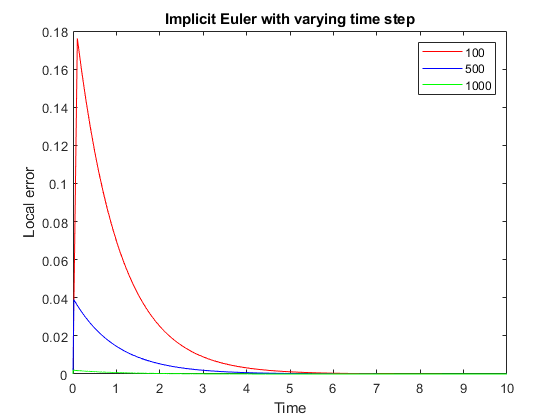

% Local error against time step

x0 = 1;
t0 = 0;
tN = 10;
N = 100;

[T,X] = ExplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T1,X1] = ImplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T2,X2] = ClassicalRungeKuttaFixedStepSize(@testEquationJac,t0,tN,N,x0);

l = local_error(T,X);
l1 = local_error(T1,X1);
l2 = local_error(T2,X2);

N = 500;

[T_1,X_1] = ExplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T1_1,X1_1] = ImplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T2_1,X2_1] = ClassicalRungeKuttaFixedStepSize(@testEquationJac,t0,tN,N,x0);

l_1 = local_error(T_1,X_1);
l1_1 = local_error(T1_1,X1_1);
l2_1 = local_error(T2_1,X2_1);

N = 10000;

[T_2,X_2] = ExplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T1_2,X1_2] = ImplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T2_2,X2_2] = ClassicalRungeKuttaFixedStepSize(@testEquationJac,t0,tN,N,x0);

l_2 = local_error(T_2,X_2);
l1_2 = local_error(T1_2,X1_2);
l2_2 = local_error(T2_2,X2_2);

plot(T,l,"r");
hold on;
plot(T_1,l_1,"b");
hold on;
plot(T_2,l_2,"g");
hold off;
title("Implicit Euler with varying time step");
legend("100","500","1000");
xlabel("Time");
ylabel("Local error");

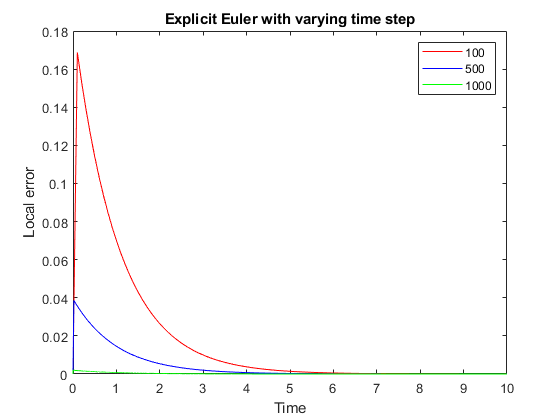

% Explicit Euler with varying time step

plot(T1,l1,"r");
hold on;
plot(T1_1,l1_1,"b");
hold on;
plot(T1_2,l1_2,"g");
hold off;
title("Explicit Euler with varying time step");
legend("100","500","1000");
xlabel("Time");
ylabel("Local error");

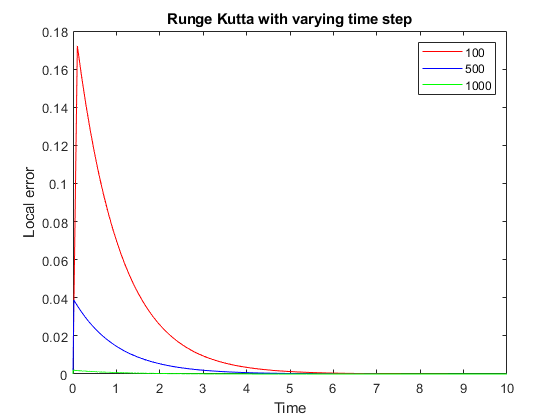

% Runge Kutta with varying time step

plot(T2,l2,"r");
hold on;
plot(T2_1,l2_1,"b");
hold on;
plot(T2_2,l2_2,"g");
hold off;
title("Runge Kutta with varying time step");
legend("100","500","1000");
xlabel("Time");
ylabel("Local error");

plot(T,l,"-r");
hold on;
plot(T_1,l_1,"r");
hold on;
plot(T1,l1,"-b");
hold on;
plot(T1_1,l1_1,"b");
hold on;
plot(T2,l2,"-c");
hold on;
plot(T2_1,l2_1,"c");
hold off;
title("Local error");
legend("Explicit Euler Method","Implicit Euler Method","Runge-Kutta");
xlabel("Time");
ylabel("Local error");

## Global error at t = 1

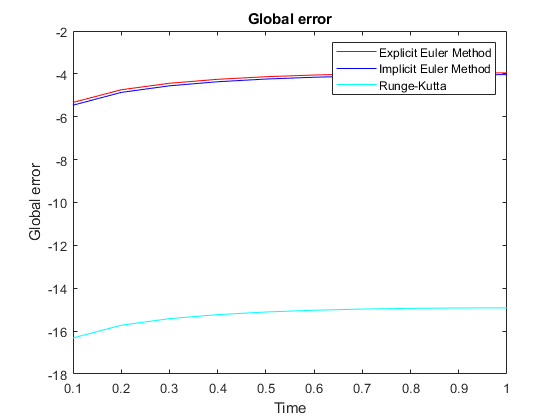

% Global truncation errors

x0 = 1;
t0 = 0;
tN = 1;
N = 10;

[T,X] = ExplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T1,X1] = ImplicitEulerFixedStepSize(@testEquationJac,t0,tN,N,x0);
[T2,X2] = ClassicalRungeKuttaFixedStepSize(@testEquationJac,t0,tN,N,x0);

g = global_error(T,X);
g1 = global_error(T1,X1);
g2 = global_error(T2,X2);

plot(T,log(abs(g)),"red");
hold on;
plot(T1,log(abs(g1)),"blue");
hold on;
plot(T2,log(abs(g2)),"cyan");
hold off;
title("Global error");
legend("Explicit Euler Method","Implicit Euler Method","Runge-Kutta");
xlabel("Time");
ylabel("Global error");